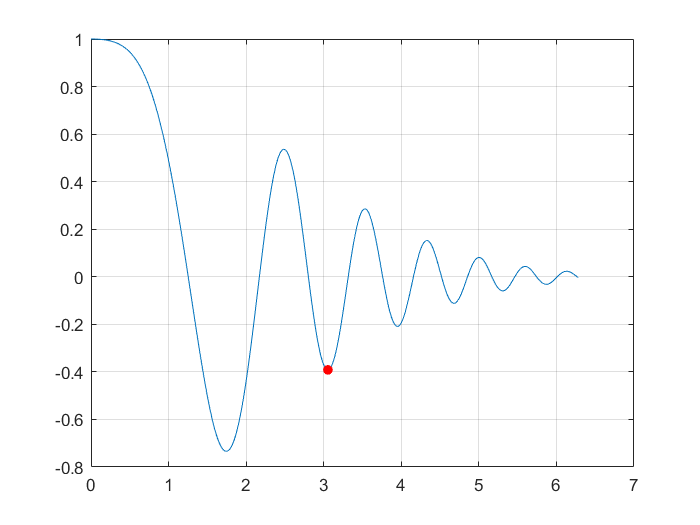

%1_a
u = 0.1;
x = 0:0.01:2*pi;
F = @(x)exp(-u*x.*x).*cos(x.*x);
y = F(x);
plot(x, y);
hold on;
grid on;
xr = ginput(2);
[x_min, y_min] = fminbnd(F, xr(1, 1), xr(2, 1));
plot(x_min, y_min, 'r.', 'MarkerSize', 20);
hold off;

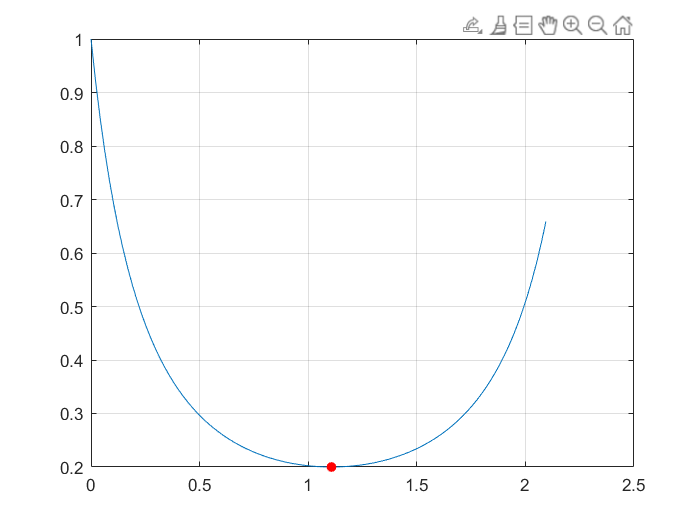

%% 1_b
clear;
a = 0;
b = 2*pi/3;
a1 = 1;
b1 = 2;
x = linspace(a, b, 100);
F = @(x)1./((a1.*cos(x)+b1.*sin(x)).^2);
y = F(x);
plot(x, y);
hold on;
grid on;
xr = ginput(2);
[x_min, y_min] = fminbnd(F, xr(1, 1), xr(2, 1));
plot(x_min, y_min, 'r.', 'MarkerSize', 20);
hold off;

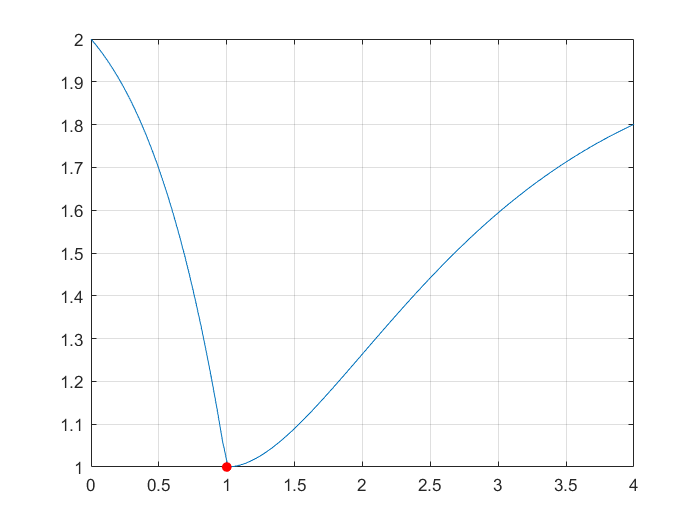

%% 1_c
a = 0;
b = 4;
x = linspace(a, b, 100);
F = @(x)2-abs(x).*exp(1).^(-abs(x-1));
y = F(x);
plot(x, y);
hold on;
grid on;
xr = ginput(2);
[x_min, y_min] = fminbnd(F, xr(1, 1), xr(2, 1));
plot(x_min, y_min, 'r.', 'MarkerSize', 20);
hold off;

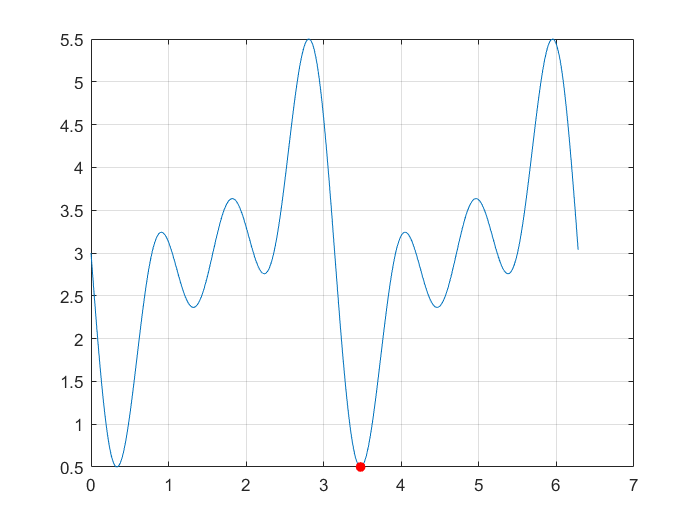

%%1_d
%syms x k;
%z = symsum(((cos(k.*x) - sin(k.*x)).^2),k,1,3);
a = 0;
b = 2*pi;
x = 0:0.01:2*pi;
F = @(x)(cos(2*x) - sin(2*x)).^2 + (cos(3*x) - sin(3*x)).^2 +(cos(x) - sin(x)).^2;
y = F(x);
plot(x, y);
hold on;
grid on;
xr = ginput(2);
[x_min, y_min] = fminbnd(F, xr(1, 1), xr(2, 1));
plot(x_min, y_min, 'r.', 'MarkerSize', 20);
hold off;

%%2_a
clear;
xr = [0 -0.2; 1 -0.2];
global alpha;
grid on;

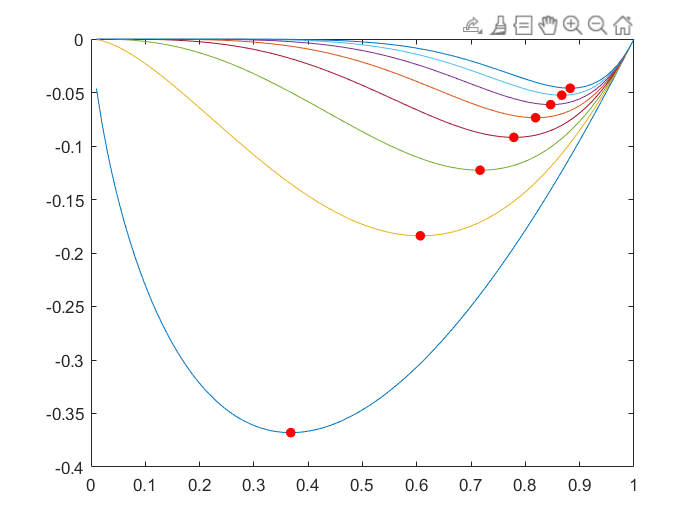

for alpha = 1:1:8
x = linspace(0, 1, 100);
y = fun_1(x);
plot(x, y);
hold on;
[x_min, y_min] = fminbnd(@fun_1, xr(1, 1), xr(2, 1));
plot(x_min, y_min, 'r.', 'MarkerSize', 20);
end
hold off;

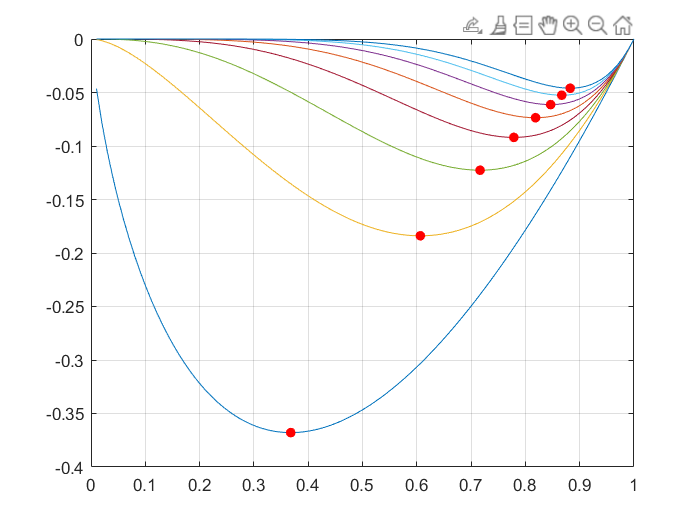

%% 2_b
clear;
xr = [0 0.1; 1 0.1];
global alpha;
global betha;
grid on;

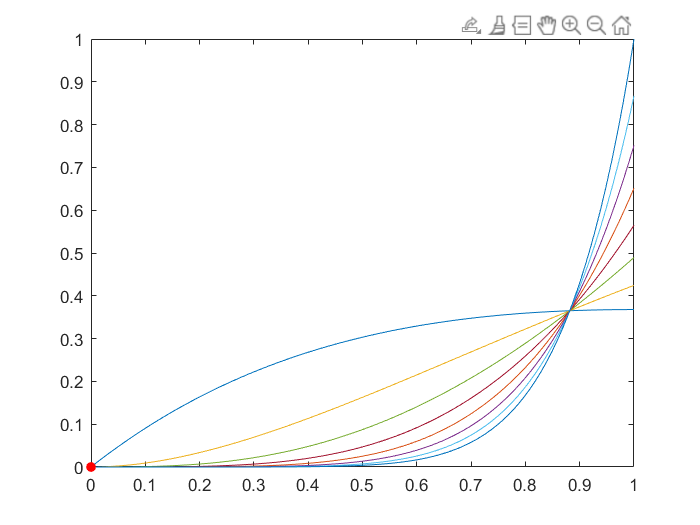

par_2 = linspace(1, 0, 8);
for par = 1:1:8
    alpha = par;
    betha = par_2(par);
    x = linspace(0, 1, 100);
    y = fun_2(x);
    plot(x, y);
    hold on;
    [x_min, y_min] = fminbnd(@fun_2, xr(1, 1), xr(2, 1));
    plot(x_min, y_min, 'r.', 'MarkerSize', 20);
end
hold off;

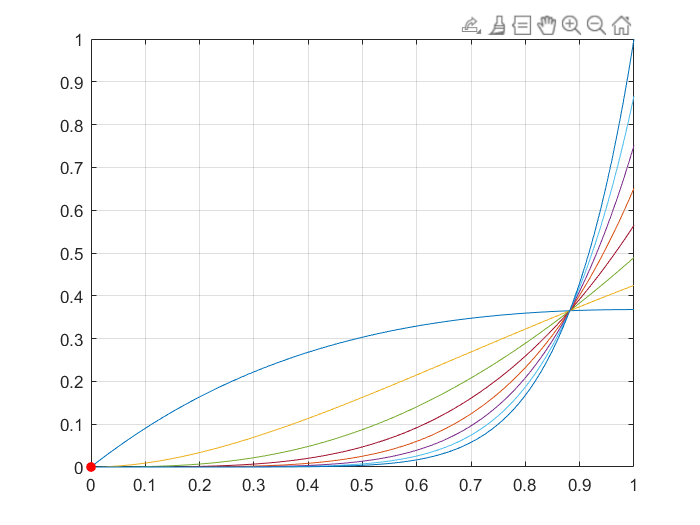

%% 2_c
clear;
xr = [0 0.1; 1 0.1];
global alpha;
global betha;
grid on;

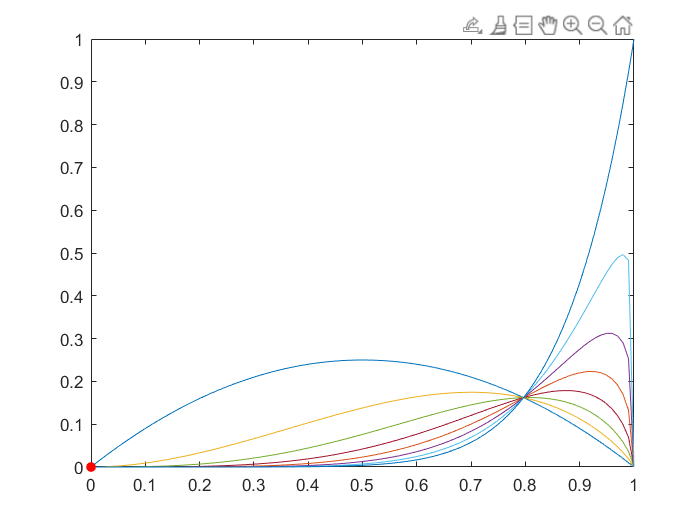

par_1 = linspace(1, 0, 8);
for par = 1:1:8
    alpha = par;
    betha = par_1(par);
    x = linspace(0, 1, 100);
    y = fun_3(x);
    plot(x, y);
    hold on;
    [x_min, y_min] = fminbnd(@fun_3, xr(1, 1), xr(2, 1));
    plot(x_min, y_min, 'r.', 'MarkerSize', 20);
end
hold off;

function f = fun_3(x)
global alpha;
global betha;
f = (x.^(alpha)).*((1-x).^betha);
end

function f = fun_2(x)
global alpha;
global betha;
f = (x.^(alpha)).*(exp(1).^(-betha.*x));
end

function f = fun_1(x)
global alpha;
f = (x.^alpha).*log(x);
end